## Runge-Kutta Methods

In this livescript, you will learn how

- To solve initial value problems using Runge-Kutta methods.

Previously, we saw that with the explicit Euler method, we saw that the value of $x_{n+1}$ is given by


$$x_{n+1}=x_{n}+\Delta tf(t_{n},x_{n})$$


However, the only problem with it was that it had a low order of convergence $\mathcal{O}(\Delta t)$. We also saw that if we included $n$ additional degrees of freedom by using the $n$ higher order derivatives, we could increase this order of converegnce to $\mathcal{O}(\Delta t)^{n+1}$. But the problem remains that we have to evaluate these derivatives, which can be quite difficult.

The main idea with Runge-Kutta methods is to estimate the derivative of $x$ using a weighted average of the gradient between $t_{n}$ and $t_{n+1}$


$$g=a_{1}k_{1}+a_{2}k_{2}+\cdots+a_{N}k_{N}$$


where the coefficients $a_{i}$ and the gradients $k_{i}$ are chosen in such a way that we can achieve the required order of convergence.

For second order convergence, we have


$$a_{1}=a_{2}=\frac{1}{2}$$



$$k_{1}=f(t_{n},x_{n}) \\
k_{2}=f(t_{n}+\Delta t,x_{n}+k_{1}\Delta t)$$


Then the value of $x_{n+1}$ is given by


$$x_{n+1}=x_{n}+\Delta tg$$


The implementation of this in MATLAB is in fact quite simple as all we have to do is include additional lines of code to estimate the derivative.

To illustrate this, consider the solution of the nonlinear problem 


$$\frac{dx}{dt}=-xt^{2}$$


with the initial condition $x(0)=1$.

As always, we'll initialise our variables and relevant parameters

k = 1;               %Growth rate
dt = 0.01;           %Step size
t = 0:dt:10;         %Time
x = zeros(size(t));  %Population size
x(1) = 1;            %Initial condition

f = @(t,x) -x.*t.^2; %Forcing Function

Then the main loop for the time stepping is given by

for i = 1:length(t)-1
    k1 = f(t(i),x(i));
    k2 = f(t(i)+dt,x(i)+k1*dt);
    g = 0.5*(k1+k2);
    x(i+1) = x(i)+g*dt;
end

plot(t,x)

Comparing with $\texttt{ode45}$ we have

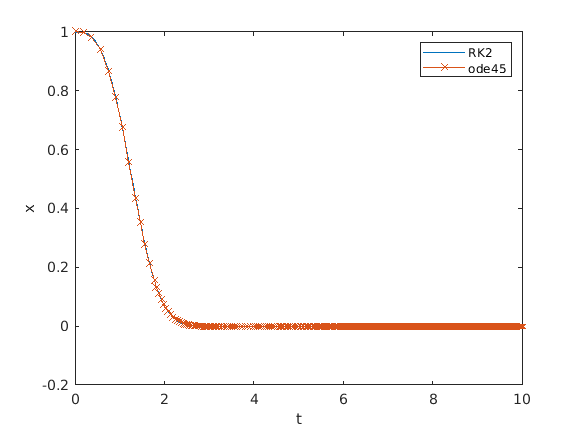

[t1,x1] = ode45(f,[0,10],1);

hold on
plot(t1,x1)
hold off

legend('RK2','ode45')
xlabel('t')
ylabel('x')

(a)        Estimate the maximum time-step such that the method is stable.

(b)        Modify the livescript to work with RK4.